## Problem 5.2a

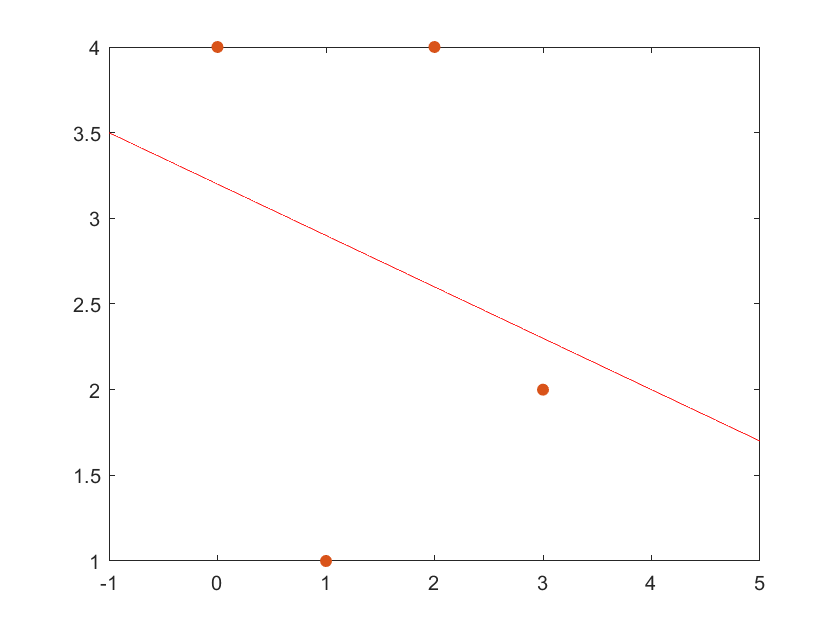

A = [1,0;1,1;1,2;1,3];
x = [0;1;2;3];
y = [4;1;4;2];

alpha = (A' * A)\(A' * y);

xvals = -1:0.01:5;
yvals = alpha(1) + alpha(2) * xvals;
plot(xvals, yvals, 'red')
hold on
scatter(x,y, 'filled')

yls = alpha(1) + alpha(2) * x;
r = y - yls

r =     0.8000
   -1.9000
    1.4000
   -0.3000


residual_norm_squared = norm(r)^2

residual_norm_squared = 6.3000

## Problem 5.2b

A = [1,0;1,1;1,2;1,3];
x = [0;1;2;3];
y = [4;1;4;2];
W = diag([1,3,3,1])

W =      1     0     0     0
     0     3     0     0
     0     0     3     0
     0     0     0     1


alpha = (A' * (W' * W) * A)\(A' * (W' * W) * y)

alpha =     0.8000
    1.1667


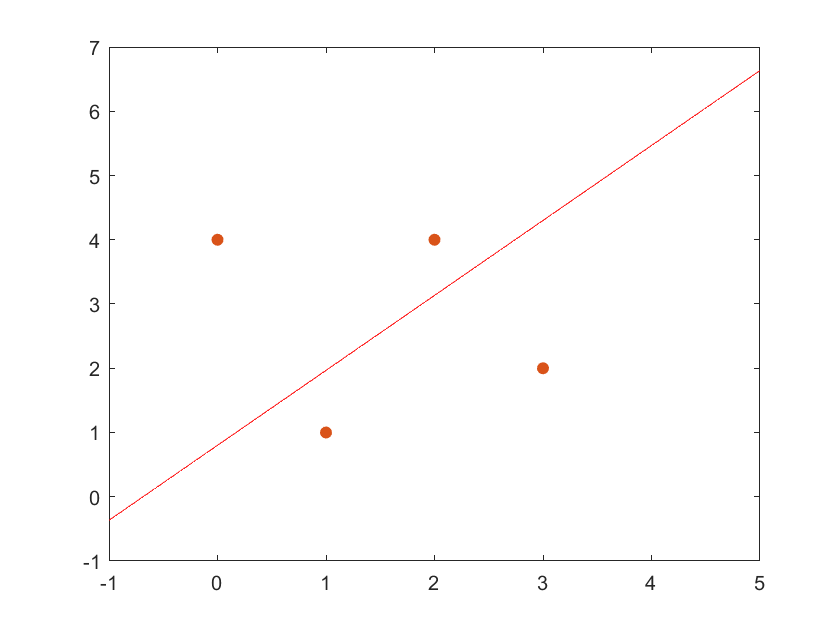

xvals = -1:0.01:5;
yvals = alpha(1) + alpha(2) * xvals;
figure;
plot(xvals, yvals, 'red')
hold on
scatter(x,y, 'filled')

yls = alpha(1) + alpha(2) * x;
r = y - yls

r =     3.2000
   -0.9667
    0.8667
   -2.3000


residual_norm_squared = norm(r)^2

residual_norm_squared = 17.2156

## Problem 5.2c

A = [1,0;1,1;1,2;1,3];
x = [0;1;2;3];
y = [4;1;4;2];
W = [1,0,0,0;0,3,1,0;0,1,3,0;0,0,0,1]

W =      1     0     0     0
     0     3     1     0
     0     1     3     0
     0     0     0     1


alpha = (A' * (W' * W) * A)\(A' * (W' * W) * y)

alpha =     1.8371
    0.4615


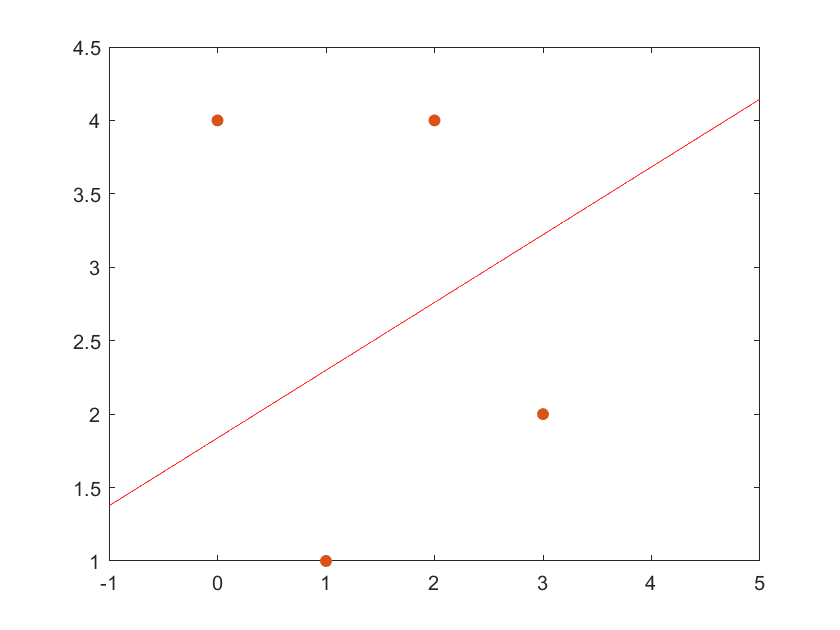

xvals = -1:0.01:5;
yvals = alpha(1) + alpha(2) * xvals;
figure;
plot(xvals, yvals, 'red')
hold on
scatter(x,y, 'filled')

yls = alpha(1) + alpha(2) * x;
r = y - yls 

r =     2.1629
   -1.2986
    1.2398
   -1.2217


residual_norm_squared = norm(r)^2

residual_norm_squared = 9.3943

## Problem 5.2d

A = [1,0;1,1;1,2;1,3];
x = [0;1;2;3];
y = [4;1;4;2];
W = [1,0,0,0;0,3,-1,0;0,-1,3,0;0,0,0,1]

W =      1     0     0     0
     0     3    -1     0
     0    -1     3     0
     0     0     0     1


alpha = (A' * (W' * W) * A)\(A' * (W' * W) * y)

alpha =     0.0800
    1.6800


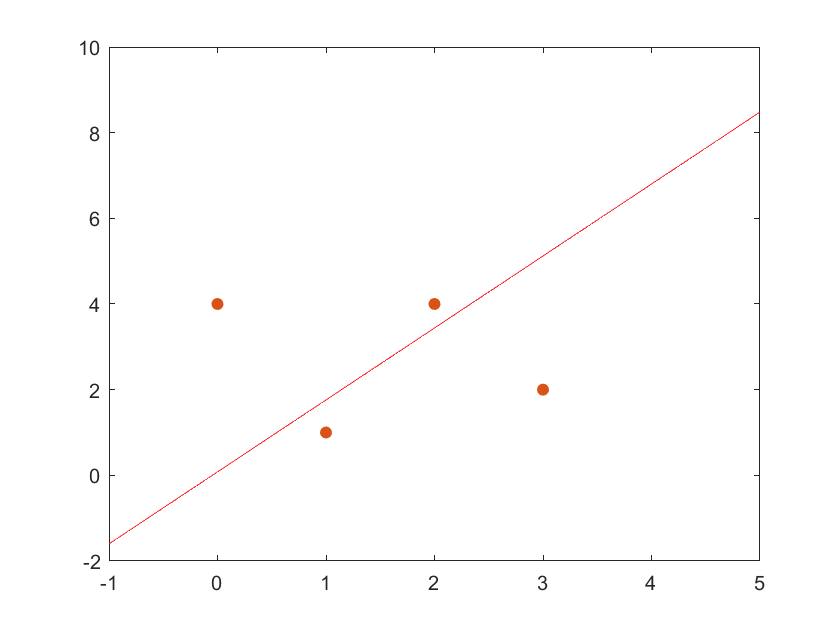

xvals = -1:0.01:5;
yvals = alpha(1) + alpha(2) * xvals;
figure;
plot(xvals, yvals, 'red')
hold on
scatter(x,y, 'filled')

yls = alpha(1) + alpha(2) * x;
r = y - yls 

r =     3.9200
   -0.7600
    0.5600
   -3.1200


residual_norm_squared = norm(r)^2

residual_norm_squared = 25.9920

## Problem 5.2e

A = [1,0,0;1,1,1;1,2,4;1,3,9];
x = [0;1;2;3];
y = [4;1;4;2];
alpha = (A' * A)\(A' * y)

alpha =     3.4500
   -1.0500
    0.2500


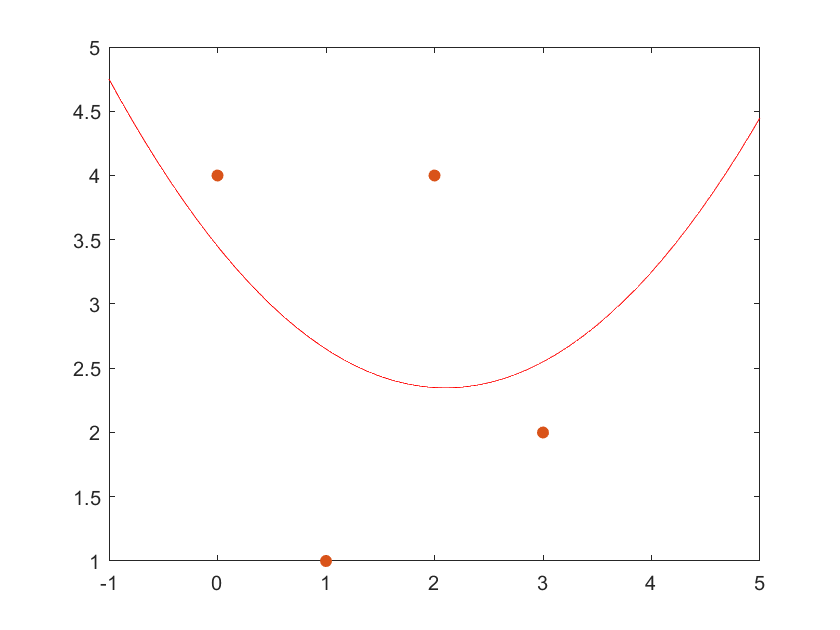

xvals = -1:0.01:5;
yvals = alpha(1) + alpha(2) * xvals + alpha(3) * xvals.^2;
figure;
plot(xvals, yvals, 'red')
hold on
scatter(x,y, 'filled')

yls = alpha(1) + alpha(2) * x + alpha(3) * x.^2;
r = y - yls 

r =     0.5500
   -1.6500
    1.6500
   -0.5500


residual_norm_squared = norm(r)^2

residual_norm_squared = 6.0500

Acubic = [1,0,0,0;1,1,1,1;1,2,4,8;1,3,9,27];
alphacubic = (Acubic' * Acubic)\(Acubic' * y)

alphacubic =     4.0000
   -9.6667
    8.5000
   -1.8333


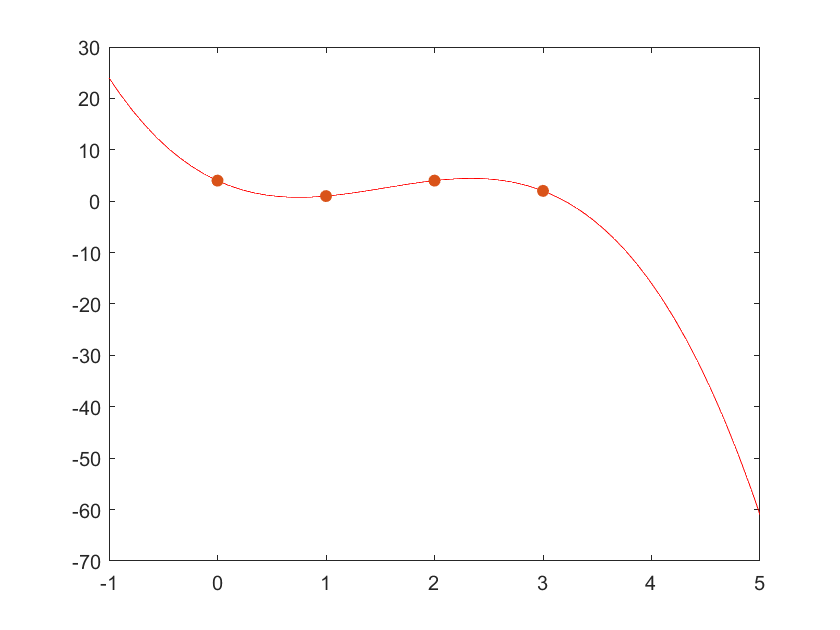

xvals = -1:0.01:5;
yvalscubic = alphacubic(1) + alphacubic(2) * xvals + alphacubic(3) * xvals.^2 + alphacubic(4) * xvals.^3;
figure;
plot(xvals, yvalscubic, 'red')
hold on
scatter(x,y, 'filled')

ylscubic = alphacubic(1) + alphacubic(2) * x + alphacubic(3) * x.^2 + alphacubic(4) * x.^3;
rcubic = y - ylscubic 

rcubic = 	1.0e+-13 *

    0.2132
   -0.4508
    0.3020
   -0.0711


cubicresidual_norm_squared = norm(rcubic)^2

cubicresidual_norm_squared = 3.4486e-27

## Problem 5.2f

A0 = [1,0,0,0;1,1,1,1;1,2,4,8;1,3,9,27;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0];
A1 = [1,0,0,0;1,1,1,1;1,2,4,8;1,3,9,27;sqrt(0.05),0,0,0;0,sqrt(0.05),0,0;0,0,sqrt(0.05),0;0,0,0,sqrt(0.05)];
A2 = [1,0,0,0;1,1,1,1;1,2,4,8;1,3,9,27;sqrt(0.5),0,0,0;0,sqrt(0.5),0,0;0,0,sqrt(0.5),0;0,0,0,sqrt(0.5)];
y = [4;1;4;2;0;0;0;0];
alpha0 = (A0' * A0)\(A0' * y)

alpha0 =     4.0000
   -9.6667
    8.5000
   -1.8333


alpha1 = (A1' * A1)\(A1' * y)

alpha1 =     3.2787
   -4.0273
    3.6308
   -0.8040


alpha2 = (A2' * A2)\(A2' * y)

alpha2 =     2.2138
   -0.2946
    0.7807
   -0.2257


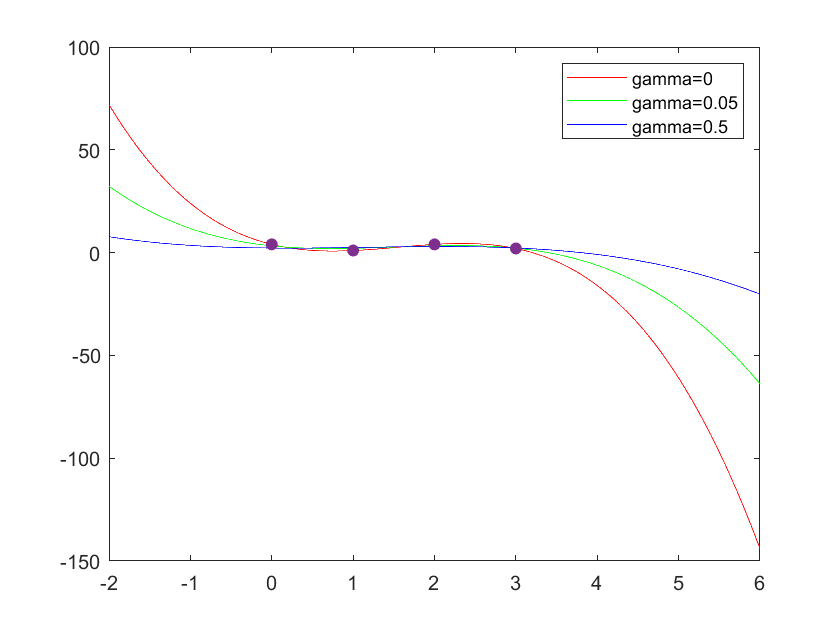

xvals = -2:0.01:6;
yvals0 = alpha0(1) + alpha0(2) * xvals + alpha0(3) * xvals.^2 + alpha0(4) * xvals.^3;
yvals1 = alpha1(1) + alpha1(2) * xvals + alpha1(3) * xvals.^2 + alpha1(4) * xvals.^3;
yvals2 = alpha2(1) + alpha2(2) * xvals + alpha2(3) * xvals.^2 + alpha2(4) * xvals.^3;
figure;
plot(xvals, yvals0, 'red')
hold on
plot(xvals, yvals1, 'green')
hold on
plot(xvals, yvals2, 'blue')
hold on
scatter(x,y(1:4), 'filled')
legend('gamma=0', 'gamma=0.05', 'gamma=0.5')

## Problem 5.7b

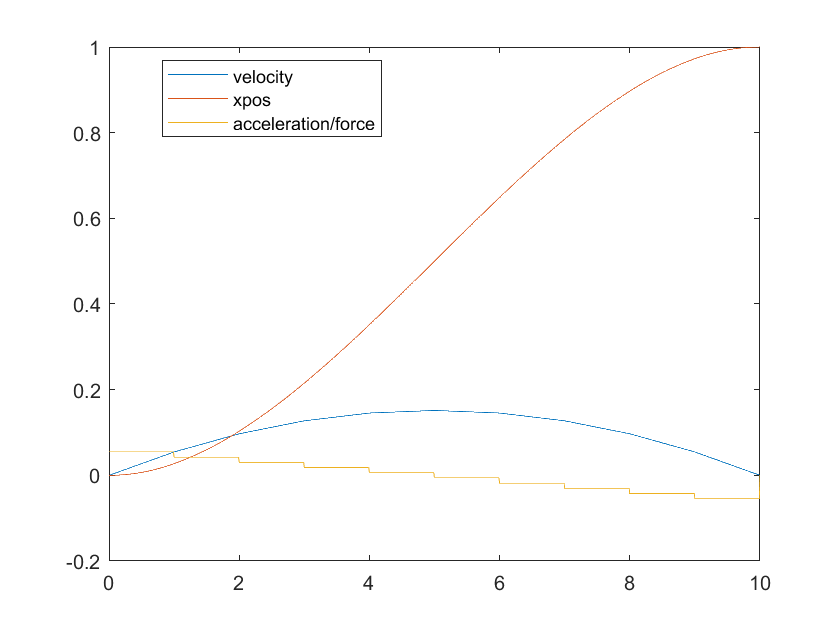

A = [1,1;0,1];
b = [0.5;1];
Als = [A^9*b A^8*b A^7*b A^6*b A^5*b A^4*b A^3*b A^2*b A*b b];
yls = [1;0];
pls = pinv(Als)*yls;
norm(pls);
pos = [0];
vel = [0];
for i=1:10
    step = A*[pos(end); vel(end)] + pls(i)*b;
    pos = [pos step(1)];
    vel = [vel step(2)];
end
pos;
vel;
timesteps = 0:0.01:10;
pn = [pls; 0];
f = @(t) pn(floor(t)+1);
xbar = @(t) vel(floor(t)+1) + pn(floor(t)+1) * (t - floor(t));
x = @(t) pos(floor(t)+1) + vel(floor(t)+1) * (t-floor(t)) + pn(floor(t)+1) * (0.5*(t.^2-(floor(t))^2) - floor(t)*(t-floor(t)));
% 
figure;
plot(timesteps, arrayfun(xbar, timesteps))
hold on
plot(timesteps, arrayfun(x, timesteps))
hold on
plot(timesteps, arrayfun(f, timesteps))
legend('velocity', 'xpos', 'acceleration/force', 'Location', 'Best')

## Problem 5.7c

A = [1,1;0,1];
b = [0.5;1];
Als1 = [A^9*b A^8*b A^7*b A^6*b A^5*b A^4*b A^3*b A^2*b A*b b];
Als2tmp = [A^4*b A^3*b A^2*b A*b b];
z = [0;0];
Als2 = [Als2tmp z z z z z];
Als = [Als1; Als2];
Als = Als(1:3, :)

Als =     9.5000    8.5000    7.5000    6.5000    5.5000    4.5000    3.5000    2.5000    1.5000    0.5000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    4.5000    3.5000    2.5000    1.5000    0.5000         0         0         0         0         0


yls = [1;0;0]

yls =      1
     0
     0


pls = pinv(Als)*yls

pls =    -0.0455
   -0.0076
    0.0303
    0.0682
    0.1061
    0.0939
    0.0318
   -0.0303
   -0.0924
   -0.1545


norm(pls)

ans = 0.2492

pos = [0];
vel = [0];
for i=1:10
    step = A*[pos(end); vel(end)] + pls(i)*b;
    pos = [pos step(1)];
    vel = [vel step(2)];
end
pos

pos =          0   -0.0227   -0.0720   -0.1098   -0.0985    0.0000    0.1985    0.4598    0.7220    0.9227    1.0000


vel

vel =          0   -0.0455   -0.0530   -0.0227    0.0455    0.1515    0.2455    0.2773    0.2470    0.1545   -0.0000


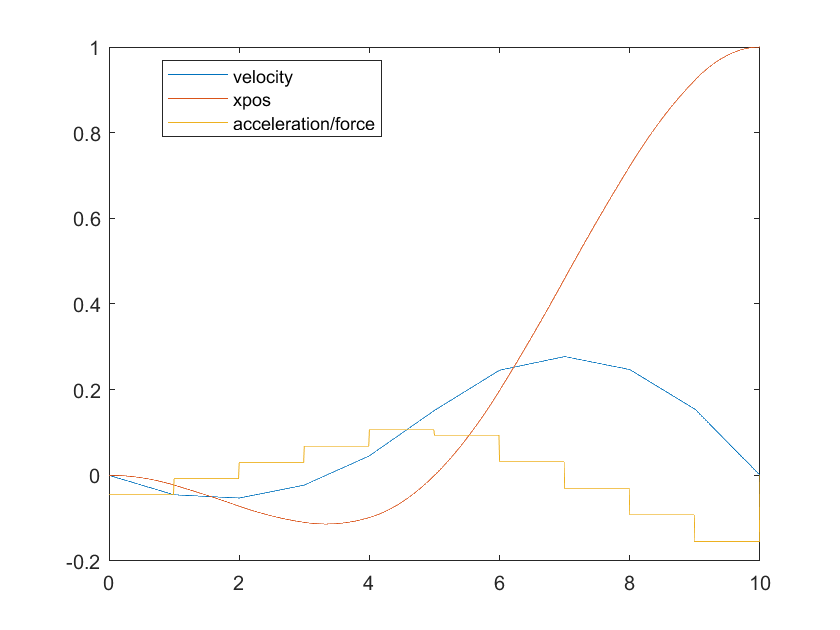

timesteps = 0:0.01:10;
pn = [pls; 0];
f = @(t) pn(floor(t)+1);
xbar = @(t) vel(floor(t)+1) + pn(floor(t)+1) * (t - floor(t));
x = @(t) pos(floor(t)+1) + vel(floor(t)+1) * (t-floor(t)) + pn(floor(t)+1) * (0.5*(t.^2-(floor(t))^2) - floor(t)*(t-floor(t)));
% 
figure;
plot(timesteps, arrayfun(xbar, timesteps))
hold on
plot(timesteps, arrayfun(x, timesteps))
hold on
plot(timesteps, arrayfun(f, timesteps))
legend('velocity', 'xpos', 'acceleration/force', 'Location', 'Best')